clear, clc, close all;
datetime("now")

ans = datetime
   12-Nov-2023 17:56:09



RTD_input;

## Задание начальных параметров

Nx = 8000;
NVb = 700;

dx = (L + 1000) / (Nx + 1);
d = dx * round(d / dx);
xv = linspace(-500, L + 500, Nx + 2);

Vfin = 0.5 / V_Hartree_SI;
Vbv = linspace(0, Vfin, NVb);

Ux_mat = zeros(Nx + 2, NVb);
for Vj = 1 : NVb
    [Ux_mat(:,Vj), ~] = simp_ux_mx(xv, (U0), Vbv(Vj), xb, d, md, mw, E_0);
end

PSI_EC = zeros(Nx + 2, NVb);

## Находим волновую функцию

for jQ = 1 : NVb
    VjQ = Vbv(jQ);
    
    EkQ = 1.5 / Eh_eV;
    PSI_EC(:, jQ) = QTBM_func_Hartree(xv, U0, VjQ, EkQ, xb, d, md, mw, E_0, 1, 0);
end

## График при напряжении смещения 0 мВ

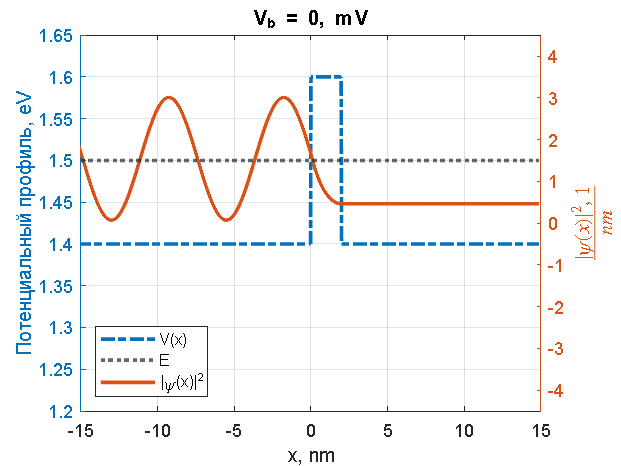

yyaxis left;
plot(xv / nm_a0_sf, Ux_mat(:, 1) * Eh_eV, '-.', 'LineWidth', 2);
hold on;
yline(EkQ * Eh_eV, ':', 'LineWidth', 2);
ylim([1.2, 1.65]);
ylabel('Потенциальный профиль, eV')
xlabel('x, nm');

yyaxis right;
plot(xv / nm_a0_sf, abs(PSI_EC(:,1)) .^ 2, 'LineWidth', 2);
ylim([-4.5,4.5]);
ylabel('$|\psi(x)|^2$, $1\over nm$', 'Interpreter', 'latex');
xlim([-15, 15]);
grid on;
legend('V(x)', 'E', '|\psi(x)|^2', 'Location', 'southwest');
title('V_b = 0, mV');